## Part 1

T1a = readtable("Lab2-Part1a");

T1b = readtable("Lab2-Part1b");

T1c = readtable("Lab2-Part1c");

T1d = readtable("Lab2-Part1d");

mass1 = trapz(T1a.Time_s_, T1a.MassFlowrate_g_min_ ./ 60)

mass1 = 23.6203

mass2 = trapz(T1b.Time_s_, T1b.MassFlowrate_g_min_ ./ 60)

mass2 = 41.3050

mass3 = trapz(T1c.Time_s_, T1c.MassFlowrate_g_min_ ./ 60)

mass3 = 22.0523

mass4 = trapz(T1d.Time_s_, T1d.MassFlowrate_g_min_ ./ 60)

mass4 = 40.4365

% Convert pressures to Pa
p1 = T1a.P1_PSI_ .* 6894.76;
p2 = T1b.P1_PSI_ .* 6894.76;
p3 = T1c.P1_PSI_ .* 6894.76;
p4 = T1d.P1_PSI_ .* 6894.76;
%  Convert temperatures to K
temp1 = T1a.T1_DegC_ + 273.15;
temp2 = T1b.T1_DegC_ + 273.15;
temp3 = T1c.T1_DegC_ + 273.15;
temp4 = T1d.T1_DegC_ + 273.15;
% Calculate masses
m_left_1 = mass1 * (1 + (1/(((p1(end)*temp1(1))/(p1(1)*temp1(end)))-1)))

m_left_1 = 23.6800

m_left_2 = mass2 * (1 + (1/(((p2(end)*temp2(1))/(p2(1)*temp2(end)))-1))) 

m_left_2 = 41.5432

m_left_3 = mass3 * (1 + (1/(((p3(end)*temp3(1))/(p3(1)*temp3(end)))-1))) 

m_left_3 = 22.3962

m_left_4 = mass4 * (1 + (1/(((p4(end)*temp4(1))/(p4(1)*temp4(end)))-1))) 

m_left_4 = 40.9709

## Part 2

T2a = readtable("Lab2-Part2a");

T2b = readtable("Lab2-Part2b");

T2c = readtable("Lab2-Part2c");

T2d = readtable("Lab2-Part2d");

Plot 1

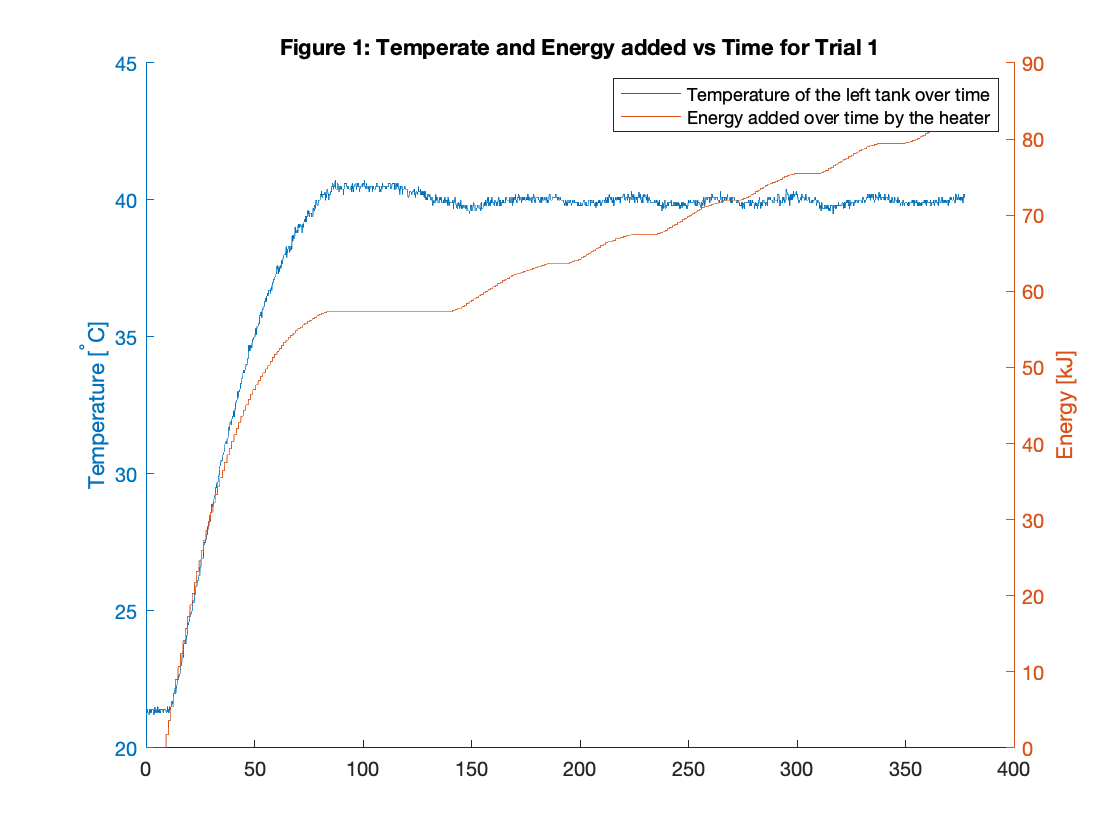

hold on
yyaxis left;
plot(T2a.Time_s_, T2a.T1_DegC_);
ylabel("Temperature [^{\circ}C]");
yyaxis right;
plot(T2a.Time_s_, T2a.HeaterEnergy_kJ_);
ylabel("Energy [kJ]");
legend("Temperature of the left tank over time", "Energy added over time by the heater");
title("Figure 1: Temperate and Energy added vs Time for Trial 1");
hold off

Plot 2

% yyaxis left;
% plot(T2b.Time_s_, T2b.T1_DegC_);
% ylabel("Temperature [^{\circ}C]")
% yyaxis right;
% plot(T2b.Time_s_, T2b.HeaterEnergy_kJ_);
% ylabel("Energy [kJ]")
% legend("Temperature of the left tank over time", "Energy added over time by the heater");
% title("Figure 2: Temperate and Energy added vs Time for Trial 2");

Plot 3

% yyaxis left;
% plot(T2c.Time_s_, T2c.T1_DegC_);
% ylabel("Temperature [^{\circ}C]")
% yyaxis right;
% plot(T2c.Time_s_, T2c.HeaterEnergy_kJ_);
% ylabel("Energy [kJ]")
% legend("Temperature of the left tank over time", "Energy added over time by the heater");
% title("Figure 3: Temperate and Energy added vs Time for Trial 3");

### Plot 4

% yyaxis left;
% plot(T2d.Time_s_, T2d.T1_DegC_);
% ylabel("Temperature [^{\circ}C]")
% yyaxis right;
% plot(T2d.Time_s_, T2d.HeaterEnergy_kJ_);
% ylabel("Energy [kJ]")
% legend("Temperature of the left tank over time", "Energy added over time by the heater");
% title("Figure 4: Temperate and Energy added vs Time for Trial 4");

### Power

t1 = 139.6 % From inspection

t1 = 139.6000

t2 = 112.6 % From inspection

t2 = 112.6000

t3 = 126.1 % From inspection

t3 = 126.1000

t4 = 113.2 % From inspection

t4 = 113.2000

i = @(t) t*10 + 1;
Q1_tot = T2a.HeaterEnergy_kJ_(end)-T2a.HeaterEnergy_kJ_(i(t1))

Q1_tot = 26.2000

Q2_tot = T2b.HeaterEnergy_kJ_(end)-T2b.HeaterEnergy_kJ_(i(t2))

Q2_tot = 28.5000

Q3_tot = T2c.HeaterEnergy_kJ_(end)-T2c.HeaterEnergy_kJ_(i(t3))

Q3_tot = 46.4000

Q4_tot = T2d.HeaterEnergy_kJ_(end)-T2d.HeaterEnergy_kJ_(i(t4))

Q4_tot = 55.7000

Q = @(T,t) 2.*0.17.*pi.*0.28575.*((T-21)./log(0.2032/0.193675));
% Q1 = trapz(T2a.Time_s_(i(t1):end),Q(T2a.T1_DegC_(i(t1):end),T2a.Time_s_(i(t1):end)))
Q1 = Q(40,T2a.Time_s_(i(t1):end))*(T2a.Time_s_(end)-T2a.Time_s_(i(t1))) ./ (10^3)

Q1 = 28.7610

Q2 = Q(40,T2b.Time_s_(i(t2):end))*(T2b.Time_s_(end)-T2b.Time_s_(i(t2))) ./ (10^3)

Q2 = 31.1406

Q3 = Q(60,T2c.Time_s_(i(t3):end))*(T2c.Time_s_(end)-T2c.Time_s_(i(t3))) ./ (10^3)

Q3 = 66.5484

Q4 = Q(60,T2d.Time_s_(i(t4):end))*(T2d.Time_s_(end)-T2d.Time_s_(i(t4))) ./ (10^3)

Q4 = 68.2344


Q_tb1 = (Q1_tot)-Q1

Q_tb1 = -2.5610

Q_tb2 = (Q2_tot)-Q2

Q_tb2 = -2.6406

Q_tb3 = (Q3_tot)-Q3

Q_tb3 = -20.1484

Q_tb4 = (Q4_tot)-Q4

Q_tb4 = -12.5344